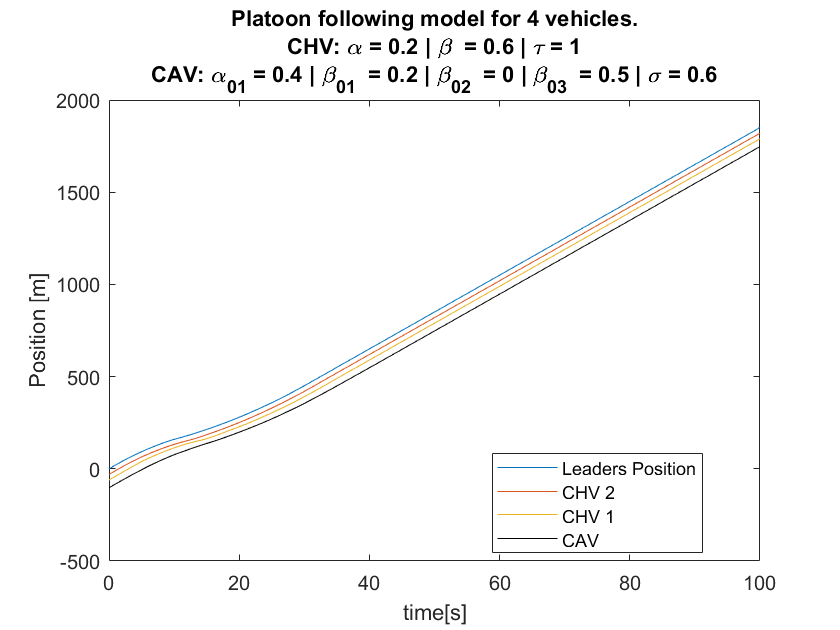

% Simulation for 4 connected vehicles: 1CAV + 3CHVs
%HW7 Q1_e

clear all;
close all;

follow_num = 2;
vehicle_num = 4;
vehicle_length = 4;

%fixed parameters for CAV
hstop = 5;
hgo = 55;
vmax = 30;
amin = 8;
amax = 3;


a = 1;
b = 0.5;
hstar_chv = 26.13;
vstar_chv = 20;

%parameters for CAV
alpha01 = 0.4;
beta01 = 0.2;
beta02 = 0;
beta03 = 0.5;
kappa0 = 0.6;
sigma = 0.6;
hstar_cav = 38.33;
vstar_cav = 20;

%parameters for CHVs
alphah = 0.2;
betah = 0.6;
tau = 1;


%simulation time
t0 = 0;
deltat = 0.1;
tend = 100;
tspan = t0:deltat:tend;

%for integrating leader's velocity
ic_vlead = 0;
sol_dde_vlead = dde23(@(t,y,ytau)ddefun_vlead(t,y,ytau,vstar_chv,a,b,tau),tau,ic_vlead,tspan);
y_vlead_position = deval(sol_dde_vlead,tspan);

%for CHV
s0 = [(-hstar_chv-vehicle_length) (-2*hstar_chv-2*vehicle_length)]'.*ones(follow_num,1);
h0 = hstar_chv*ones(follow_num,1);
vh0 = vstar_chv*ones(follow_num,1);
ic_chv = @(t)[s0 h0 vh0];

sol_chv = dde23(@(t,y,ytau)ddefun_chv(t,y,ytau,follow_num,alphah,betah,vstar_chv,a,b,vmax,hstop,hgo,tau),tau,ic_chv,tspan);
y_chv = deval(sol_chv,tspan);

positions = y_chv(1:follow_num,:);         
headways = y_chv(follow_num+1:2*follow_num,:);
velocities = y_chv(2*follow_num+1:end,:);

%for CAV
ic_cav = @(t)[-(follow_num*hstar_chv + hstar_cav + (follow_num+1)*vehicle_length) hstar_cav vstar_cav];

sol_cav = dde23(@(t,y,ysigma)ddefun_cav(t,y,ysigma,alpha01,beta01,beta02,beta03,kappa0,vmax,hstop,hgo,y_chv,tau,vstar_cav,a,b,tspan),sigma,ic_cav,tspan);
y_cav = deval(sol_cav,tspan);

position_cav = y_cav(1,:);
headway_cav = y_cav(2,:);
velocity_cav = y_cav(3,:);

figure(1);hold on ; box on;
plot(tspan,y_vlead_position);
plot(tspan,positions);
plot(tspan,position_cav,'k');
xlabel('time[s]');
ylabel('Position [m]');
title({"Platoon following model for "+vehicle_num+ " vehicles.",...
       "CHV: \alpha = "+alphah+" | \beta  = "+betah+" | \tau = "+tau ,...
       "CAV: \alpha_{01} = "+alpha01+" | \beta_{01}  = "+beta01+" | \beta_{02}  = "+beta02+" | \beta_{03}  = "+beta03+" | \sigma = "+sigma});
legend({'Leaders Position',"CHV 2","CHV 1","CAV"},'Location',"best");

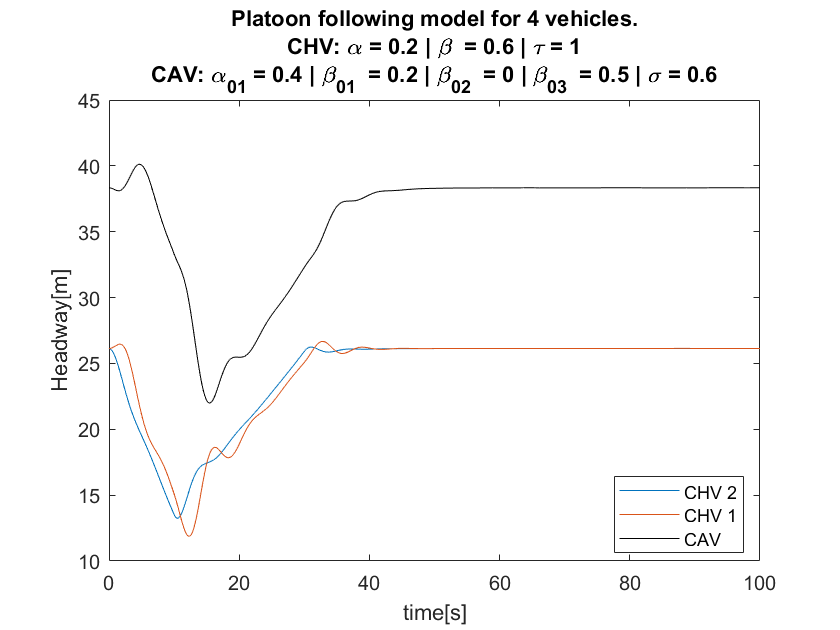


figure(2); hold on ; box on;
plot(tspan,headways);
plot(tspan,headway_cav,'k');
xlabel('time[s]');
ylabel('Headway[m]');
title({"Platoon following model for "+vehicle_num+ " vehicles.",...
       "CHV: \alpha = "+alphah+" | \beta  = "+betah+" | \tau = "+tau ,...
       "CAV: \alpha_{01} = "+alpha01+" | \beta_{01}  = "+beta01+" | \beta_{02}  = "+beta02+" | \beta_{03}  = "+beta03+" | \sigma = "+sigma});
legend({'CHV 2','CHV 1','CAV'},'Location',"best");

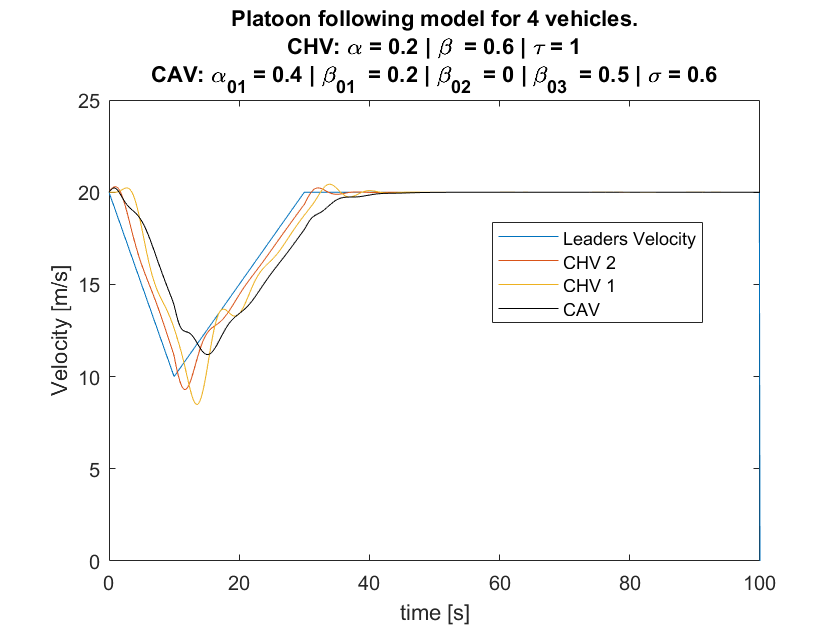

   
figure(3); hold on; box on;
plot(tspan,vlead_func(tspan,vstar_chv,a,b));
plot(tspan,velocities);
plot(tspan,velocity_cav,'k');
xlabel('time [s]');
ylabel('Velocity [m/s]');
title({"Platoon following model for "+vehicle_num+ " vehicles.",...
       "CHV: \alpha = "+alphah+" | \beta  = "+betah+" | \tau = "+tau ,...
       "CAV: \alpha_{01} = "+alpha01+" | \beta_{01}  = "+beta01+" | \beta_{02}  = "+beta02+" | \beta_{03}  = "+beta03+" | \sigma = "+sigma});
legend({'Leaders Velocity',"CHV 2","CHV 1","CAV"},'Location',"best");

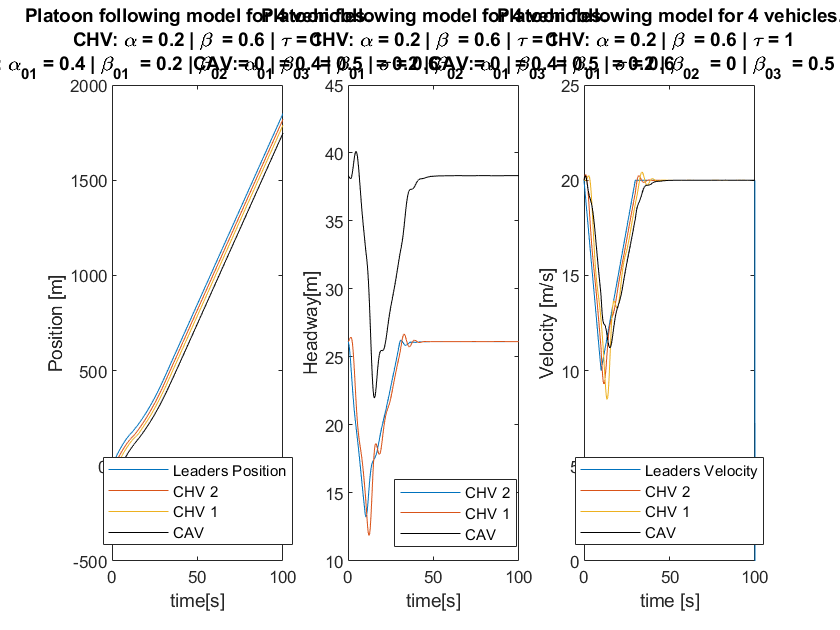



figure(4);
subplot(1,3,1);hold on;box on;
plot(tspan,y_vlead_position);
plot(tspan,positions);
plot(tspan,position_cav,'k');
xlabel('time[s]');
ylabel('Position [m]');
title({"Platoon following model for "+vehicle_num+ " vehicles.",...
       "CHV: \alpha = "+alphah+" | \beta  = "+betah+" | \tau = "+tau ,...
       "CAV: \alpha_{01} = "+alpha01+" | \beta_{01}  = "+beta01+" | \beta_{02}  = "+beta02+" | \beta_{03}  = "+beta03+" | \sigma = "+sigma});
legend({'Leaders Position',"CHV 2","CHV 1","CAV"},'Location',"best");

subplot(1,3,2);hold on;box on;
plot(tspan,headways);
plot(tspan,headway_cav,'k');
xlabel('time[s]');
ylabel('Headway[m]');
title({"Platoon following model for "+vehicle_num+ " vehicles.",...
       "CHV: \alpha = "+alphah+" | \beta  = "+betah+" | \tau = "+tau ,...
       "CAV: \alpha_{01} = "+alpha01+" | \beta_{01}  = "+beta01+" | \beta_{02}  = "+beta02+" | \beta_{03}  = "+beta03+" | \sigma = "+sigma});
legend({'CHV 2','CHV 1','CAV'},'Location',"best");

subplot(1,3,3);hold on;box on;
plot(tspan,vlead_func(tspan,vstar_chv,a,b));
plot(tspan,velocities);
plot(tspan,velocity_cav,'k');
xlabel('time [s]');
ylabel('Velocity [m/s]');
title({"Platoon following model for "+vehicle_num+ " vehicles.",...
       "CHV: \alpha = "+alphah+" | \beta  = "+betah+" | \tau = "+tau ,...
       "CAV: \alpha_{01} = "+alpha01+" | \beta_{01}  = "+beta01+" | \beta_{02}  = "+beta02+" | \beta_{03}  = "+beta03+" | \sigma = "+sigma});
legend({'Leaders Velocity',"CHV 2","CHV 1","CAV"},'Location',"best");

   function dydt = ddefun_vlead(t,y,ytau,vstar_chv,a,b,tau)
        dydt = vlead_func_delayed(t,vstar_chv,a,b,tau);
   end
   
   
function dydt = ddefun_chv(t,y,ytau,follow_num,alphah,betah,vstar_chv,a,b,vmax,hstop,hgo,tau) 
    
    s = y(1:follow_num);
    h = y(follow_num+1:2*follow_num);
    vF = y(2*follow_num+1:end);
    vL = [vlead_func(t,vstar_chv,a,b);
      vF(1:follow_num-1)] ;
  
    stau = ytau(1:follow_num);
    htau = ytau(follow_num+1:2*follow_num);
    vFtau = ytau(2*follow_num+1:end);
    vLtau = [vlead_func_delayed(t,vstar_chv,a,b,tau);
          vFtau(1:follow_num-1)] ;
      
    %Range Policy
    Vh = 0 + ((hstop<h)&(h<hgo)).*((2*hgo - hstop - htau).*(htau-hstop)*vmax/(hgo-hstop)^2) + (h>=hgo).*(vmax);
    Vhtau = 0 + ((hstop<h)&(h<hgo)).*((2*hgo - hstop - htau).*(htau-hstop)*vmax/(hgo-hstop)^2) + (h>=hgo).*(vmax);
    
    dydt = [ y(5) ; y(6) ;(vL-vF); alphah.*(Vhtau-vFtau)+betah.*(vLtau-vFtau)];

end

function dydt = ddefun_cav(t,y,ysigma,alpha01,beta01,beta02,beta03,kappa0,vmax,hstop,hgo,y_chv,tau,vstar_cav,a,b,tspan)

    Vhsigma = 0 + ((hstop<y(2))&(y(2)<hgo)).*kappa0*(ysigma(2)-hstop) + (y(2)>=hgo).*(vmax);
    
    vLead1 = @(t)interp1(tspan,y_chv(6,:),t,'linear','extrap');
    vLead2 = @(t)interp1(tspan,y_chv(5,:),t,'linear','extrap');
    
    dydt(1) = y(3);
    dydt(2) = vLead1(t) - y(3);
    dydt(3) = alpha01*Vhsigma - (alpha01 + beta01 + beta02 + beta03).*ysigma(3) +...
              beta01.*vLead1(t) + beta02.*vLead2(t) + beta03.*vlead_func_delayed(t,vstar_cav,a,b,tau) ; 
    
    dydt = dydt';
end


function vl = vlead_func(t,vstar,a,b)
%Velocity profile fron HW2 Q1
t1 = 10;
t2 = 30;
t3 = 100;
    vl = ((0<=t)&(t<t1)).*(vstar - a.*t) +...
         ((t1<=t)&(t<t2)).*(vstar + b.*(t-t2)) +...
         ((t2<=t)&(t<t3)).*vstar;      

%   vl =15+ 6*cos(t);

% %Velocity profile from HW6 Q2. Deceleration of -10[m/s2]. Although
% % acceleration feedback here. Velocity profile is taken from HW6 just to
% % compare the results.
% t1 = 1.5; %Stopping time taken from HW6.
% vl_acc = 10;    
% vl=(vstar-vl_acc*t).*(t<=t1);
end

function vl = vlead_func_delayed(t,vstar,a,b,tau)
%Velocity profile fron HW2 Q1
t1 = 10;
t2 = 30;
t3 = 100;
    vl = ((0<=t)&(t<t1)).*(vstar - a.*(t-tau)) +...
         ((t1<=t)&(t<t2)).*(vstar + b.*((t-tau)-t2)) +...
         ((t2<=t)&(t<t3)).*vstar;      

%   vl =15+ 6*cos(t);

% %Velocity profile from HW6 Q2. Deceleration of -10[m/s2]. Although
% % acceleration feedback here. Velocity profile is taken from HW6 just to
% % compare the results.
% t1 = 1.5; %Stopping time taken from HW6.
% vl_acc = 10;    
% vl=(vstar-vl_acc*t).*(t<=t1);
end


